# YORP Effect on Defunct Satellite [Gorizont]

Numerical Simulation of the Dzhanibekov Effect with differential Moment of Inertia (mass and radial distance) using 4th-order Runge-Kutta Method.

Force-free Euler's Equations for a triaxial rigid body:


$$x_1 :\left(I_2 -I_3 \right)\omega_2 \omega_{3\;} -I_1 \dot{\omega_1 } =K_1$$



$$x_2 :\left(I_3 -I_1 \right)\omega_3 \omega_{1\;} -I_2 \dot{\omega_2 } =K_2$$



$$x_3 :\left(I_1 -I_2 \right)\omega_1 \omega_{2\;} -I_3 \dot{\omega_3 } =K_3$$


tic
clc;
clear;
clf;

Define the initial conditions of the body parameters

dt = 86400;
%86400 seconds in a day
t = 0;
% n = ;
n = (3.154e+7);
% n = 10000;
% 3.154e+7 seconds in a year
%j0 = 10;    
XOmega = deg2rad(-11.26)*0;
% Yomega = deg2rad(114.21);
Yomega = 0;
sat_i = deg2rad(1);       %satellite obliquity cannot be exactly zero
zomega = deg2rad(6);
% zomega = 2*pi/24.33;
y0 = [0; 0; zomega; XOmega; sat_i; Yomega] %313 angular velocities and angles

y0 =          0
         0
    0.1047
         0
    0.0175
         0


% y0 = [1e-1; 10; 0; 0; 0; 0; 0; 0; 0]     %initial angular velocity in the body frame (p, q, r), initial angular velocity in the inertial frame (phi, theta, psi), and initial inertia


Define body parameters

dim = 0.1

dim = 0.1000

% mm = 2000;
% xx = 7;
% yy = 5;
% zz = 4;
% % I = cube_inertia(mm, xx, yy, zz) % inertia model 
% y0(7) = I(1,1);
% y0(8) = I(2,2);
% y0(9) = I(3,3);

I1 = 2381.47;    % Moment of inertia, kg m^2
I2 = 4939.66;
I3 = 5753.96;

%Body fixed angles
p = RBI313(y0(4),y0(5),y0(6))

p =     1.0000         0         0
         0    0.9998    0.0175
         0   -0.0175    0.9998


y0(7) = (subspace([p(1,1);p(1,2);p(1,3)],[1;0;0]));
y0(8) = (subspace([p(2,1);p(2,2);p(2,3)],[0;1;0]));
y0(9) = (subspace([p(3,1);p(3,2);p(3,3)],[0;0;1]))

y0 =          0
         0
    0.1047
         0
    0.0175
         0
         0
    0.0175
    0.0175


t1(1:3) = [y0(7) y0(8) y0(9)]

t1 =          0    0.0175    0.0175


Sun position and dynamics

% YORP Dynamics
sun_i = -deg2rad(23.4);                %change this value for obliquities
s_AV = (2*pi)/3.154e+7;             %revolution in a year
% s_AV = deg2rad(12);
%(2*pi)/3.154e+7 for a year
sun_Omega = pi + deg2rad(-11.26);
% sun_Omega = 0;
sun_omega = deg2rad(114.21);
% sun_omega = 0;
y0(10:15) = [0; 0; s_AV; sun_Omega; sun_i; sun_omega]

y0 =          0
         0
    0.1047
         0
    0.0175
         0
         0
    0.0175
    0.0175
         0


s_pos = RBI313(y0(13),y0(14),y0(15))

s_pos =     0.2387   -0.9010   -0.3622
    0.9680    0.1910    0.1629
   -0.0775   -0.3895    0.9178


y0(16) = (subspace([s_pos(1,1);s_pos(1,2);s_pos(1,3)],[1;0;0]));
y0(17) = (subspace([s_pos(2,1);s_pos(2,2);s_pos(2,3)],[0;1;0]));
y0(18) = (subspace([s_pos(3,1);s_pos(3,2);s_pos(3,3)],[0;0;1]))

y0 =          0
         0
    0.1047
         0
    0.0175
         0
         0
    0.0175
    0.0175
         0


Satellite Parameters

rdif = 0.1;                %offset
Facet = {'1 Front';'1 Back';'2 Front';'2 Back'};
% rho = [0.21; 0.82; 0.21; 0.82];
rho = [0.8; 0.4; 0.8; 0.4];
s = [0.2; 0.2; 0.2; 0.2];
B = [2/3; 2/3; 2/3; 2/3];
% epsilon_f = [0.81; 0.85; 0.81; 0.85];
% epsilon_b = [0.85; 0.81; 0.85; 0.81];
epsilon_f = [1; 1; 1; 1];
epsilon_b = [0; 0; 0; 0];
n_hat = [1 0 0; -1 0 0; 1 0 0; -1 0 0];
r_hat = [0 1+rdif 0; 0 1+rdif 0; 0 -1+rdif 0; 0 -1+rdif 0];
sat_A = 3.73*5.45;
A = [sat_A; sat_A; sat_A; sat_A];

sat = table(Facet, rho, s, B, epsilon_f, epsilon_b, n_hat, r_hat, A)

sat = 4×9 table
       Facet       rho     s        B       epsilon_f    epsilon_b        n_hat               r_hat            A   
    ___________    ___    ___    _______    _________    _________    ______________    _________________    ______

    {'1 Front'}    0.8    0.2    0.66667        1            0         1     0     0    0     1.1       0    20.329
    {'1 Back' }    0.4    0.2    0.66667        1            0        -1     0     0    0     1.1       0    20.329
    {'2 Front'}    0.8    0.2    0.66667        1            0         1     0     0    0    -0.9       0    20.329
    {'2 Back' }    0.4    0.2    0.66667        1            0        -1     0     0    0    -0.9

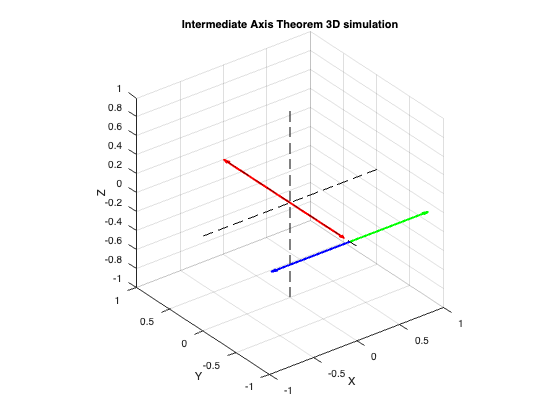

p1_nhat11 = n_hat(1,1);
p1_nhat12 = n_hat(1,2);
p1_nhat13 = n_hat(1,3);
p1_nhat21 = n_hat(2,1);
p1_nhat22 = n_hat(2,2);
p1_nhat23 = n_hat(2,3);
p2_nhat11 = n_hat(3,1);
p2_nhat12 = n_hat(3,2);
p2_nhat13 = n_hat(3,3);
p2_nhat21 = n_hat(4,1);
p2_nhat22 = n_hat(4,2);
p2_nhat23 = n_hat(4,3);

p1_rhat11 = r_hat(1,1);
p1_rhat12 = r_hat(1,2);
p1_rhat13 = r_hat(1,3);
p1_rhat21 = r_hat(2,1);
p1_rhat22 = r_hat(2,2);
p1_rhat23 = r_hat(2,3);
p2_rhat11 = r_hat(3,1);
p2_rhat12 = r_hat(3,2);
p2_rhat13 = r_hat(3,3);
p2_rhat21 = r_hat(4,1);
p2_rhat22 = r_hat(4,2);
p2_rhat23 = r_hat(4,3);
p1_rho1 = rho(1);
p1_rho2 = rho(2);
p2_rho1 = rho(3);
p2_rho2 = rho(4);
p1_s1 = s(1);
p1_s2 = s(2);
p2_s1 = s(3);
p2_s2 = s(4);
p1_e_f1 = epsilon_f(1);
p1_e_f2 = epsilon_f(2);
p2_e_f1 = epsilon_f(3);
p2_e_f2 = epsilon_f(4);
p1_e_b1 = epsilon_b(1);
p1_e_b2 = epsilon_b(2);
p2_e_b1 = epsilon_b(3);
p2_e_b2 = epsilon_b(4);
p1_A1 = A(1);
p1_A2 = A(2);
p2_A1 = A(3);
p2_A2 = A(4);

quiver3(0, 0, 0, r_hat(1,1), r_hat(1,2), r_hat(1,3), 'r', 'LineWidth', 2)
hold on
quiver3(0, 0, 0, r_hat(2,1), r_hat(2,2), r_hat(2,3), 'r', 'LineWidth', 2)
quiver3(0, 0, 0, r_hat(3,1), r_hat(3,2), r_hat(3,3), 'r', 'LineWidth', 2)
quiver3(0, 0, 0, r_hat(4,1), r_hat(4,2), r_hat(4,3), 'r', 'LineWidth', 2)

quiver3(r_hat(1,1), r_hat(1,2), r_hat(1,3), n_hat(1,1), n_hat(1,2), n_hat(1,3), 'g', 'LineWidth', 2)
quiver3(r_hat(2,1), r_hat(2,2), r_hat(2,3), n_hat(2,1), n_hat(2,2), n_hat(2,3), 'b', 'LineWidth', 2)
quiver3(r_hat(3,1), r_hat(3,2), r_hat(3,3), n_hat(3,1), n_hat(3,2), n_hat(3,3), 'g', 'LineWidth', 2)
quiver3(r_hat(4,1), r_hat(4,2), r_hat(4,3), n_hat(4,1), n_hat(4,2), n_hat(4,3), 'b', 'LineWidth', 2)

plot3([-1 1], [0 0], [0 0], 'k--')
plot3([0 0], [-1 1], [0 0], 'k--')
plot3([0 0], [0 0], [-1 1], 'k--')
xlabel('X')
ylabel('Y')
zlabel('Z')
axis equal
axis square
xlim([-1 1])
ylim([-1 1])
zlim([-1 1])
title('Intermediate Axis Theorem 3D simulation')
hold off

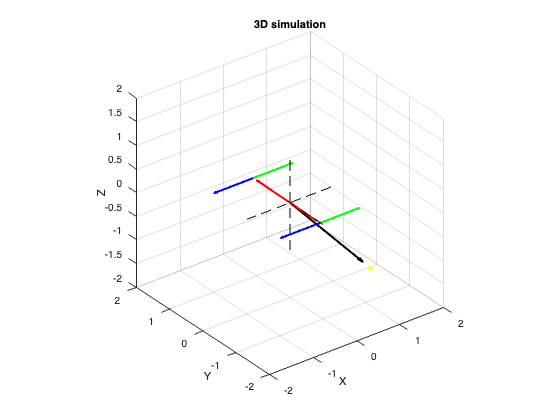

nnhat = zeros(length(n_hat),3);
nnhat(1,:) = p'*(n_hat(1,:))';
nnhat(2,:) = p'*(n_hat(2,:))';
nnhat(3,:) = p'*(n_hat(3,:))';
nnhat(4,:) = p'*(n_hat(4,:))';

rrhat = zeros(length(r_hat),3);
rrhat(1,:) = p'*(r_hat(1,:))';
rrhat(2,:) = p'*(r_hat(2,:))';
rrhat(3,:) = p'*(r_hat(3,:))';
rrhat(4,:) = p'*(r_hat(4,:))';

quiver3(rrhat(1,1), rrhat(1,2), rrhat(1,3), nnhat(1,1), nnhat(1,2), nnhat(1,3), 'g', 'LineWidth', 2)
hold on
quiver3(rrhat(2,1), rrhat(2,2), rrhat(2,3), nnhat(2,1), nnhat(2,2), nnhat(2,3), 'b', 'LineWidth', 2)
quiver3(rrhat(3,1), rrhat(3,2), rrhat(3,3), nnhat(3,1), nnhat(3,2), nnhat(3,3), 'g', 'LineWidth', 2)
quiver3(rrhat(4,1), rrhat(4,2), rrhat(4,3), nnhat(4,1), nnhat(4,2), nnhat(4,3), 'b', 'LineWidth', 2)
quiver3(0, 0, 0, s_pos(1,1)*2, s_pos(1,2)*2, s_pos(1,3)*2, 'k', 'LineWidth', 2)
quiver3(0, 0, 0, rrhat(1,1), rrhat(1,2), rrhat(1,3), 'r', 'LineWidth', 2)
quiver3(0, 0, 0, rrhat(2,1), rrhat(2,2), rrhat(2,3), 'r', 'LineWidth', 2)
quiver3(0, 0, 0, rrhat(3,1), rrhat(3,2), rrhat(3,3), 'r', 'LineWidth', 2)
quiver3(0, 0, 0, rrhat(4,1), rrhat(4,2), rrhat(4,3), 'r', 'LineWidth', 2)
plot3(s_pos(1,1)*2, s_pos(1,2)*2, s_pos(1,3)*2, 'y*')

plot3([-1 1], [0 0], [0 0], 'k--')
plot3([0 0], [-1 1], [0 0], 'k--')
plot3([0 0], [0 0], [-1 1], 'k--')
xlabel('X')
ylabel('Y')
zlabel('Z')
axis equal
axis square
xlim([-2 2])
ylim([-2 2])
zlim([-2 2])
title('3D simulation')
hold off

Sun Position Dynamics Solver (Test)

% [t,y] = ode45(@(t,y) sunyorp(t,y), 0:dt:n, y0)

ODE Solver

options = odeset('RelTol',1e-3,'AbsTol',1e-6);    %default
[t,y] = ode89(@(t,y) dza(t,y,I1,I2,I3, ...
    p1_nhat11, p1_nhat12, p1_nhat13, p1_nhat21, p1_nhat22, p1_nhat23, ...
    p2_nhat11, p2_nhat12, p2_nhat13, p2_nhat21, p2_nhat22, p2_nhat23, ...
    p1_rhat11, p1_rhat12, p1_rhat13, p1_rhat21, p1_rhat22, p1_rhat23, ...
    p2_rhat11, p2_rhat12, p2_rhat13, p2_rhat21, p2_rhat22, p2_rhat23, ...
    p1_rho1, p1_rho2, p2_rho1, p2_rho2, ...
    p1_s1, p1_s2, p2_s1, p2_s2, ...
    p1_e_f1, p1_e_f2, p2_e_f1, p2_e_f2, ...
    p1_e_b1, p1_e_b2, p2_e_b1, p2_e_b2, ...
    p1_A1, p1_A2, p2_A1, p2_A2), 0:dt:n, y0, options)

t =            0
       86400
      172800
      259200
      345600
      432000
      518400
      604800
      691200
      777600


y = 1.0e+06 *

         0         0    0.0000         0    0.0000         0         0    0.0000    0.0000         0         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0090   -0.0000    0.0000    0.0090         0         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0181   -0.0000    0.0000    0.0181         0         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0271   -0.0000    0.0000    0.0271         0         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0362   -0.0000    0.0000    0.0362         0         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0452   -0.0000    0.0000

Plot of the simulation

## **Angular Velocity**

**Satellite Body Frame**

tt = 0:12/(length(t)-1):12

tt =          0    0.0329    0.0658    0.0986    0.1315    0.1644    0.1973    0.2301    0.2630    0.2959    0.3288    0.3616    0.3945    0.4274    0.4603    0.4932    0.5260    0.5589    0.5918    0.6247    0.6575    0.6904    0.7233    0.7562    0.7890    0.8219    0.8548    0.8877    0.9205    0.9534    0.9863    1.0192    1.0521    1.0849    1.1178    1.1507    1.1836    1.2164    1.2493    1.2822    1.3151    1.3479    1.3808    1.4137    1.4466    1.4795    1.5123    1.5452    1.5781    1.6110


degsec = convangvel(y(:,1:3), 'rad/s', 'deg/s')            %Aerospace Toolbox is needed for this function to run

degsec =          0         0    6.0000
   -0.0001    0.0000    5.9997
    0.0001    0.0000    5.9994
   -0.0002   -0.0000    5.9991
   -0.0001   -0.0001    5.9988
   -0.0002    0.0000    5.9985
   -0.0002   -0.0000    5.9982
   -0.0001    0.0001    5.9979
    0.0000   -0.0000    5.9976
    0.0001   -0.0000    5.9973


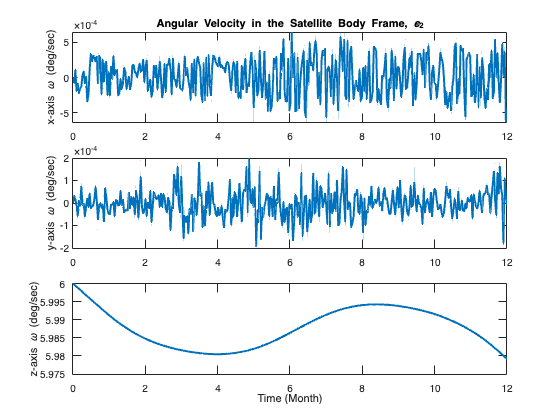


subplot(3,1,1);
plot(tt,degsec(:,1), 'LineWidth', 2)
title('Angular Velocity in the Satellite Body Frame, \epsilon_2')
ylabel('x-axis \omega (deg/sec)')
% xlabel('Time (Hours)')
% xticks(0:24:length(t))
xlim([0 tt(end)])

subplot(3,1,2);
plot(tt,degsec(:,2), 'LineWidth', 2)
% title('Angular Velocity in the Satellite Body Frame')
ylabel('y-axis \omega (deg/sec)')
% xlabel('Time (Hours)')
xlim([0 tt(end)])

subplot(3,1,3);
plot(tt,degsec(:,3), 'LineWidth', 2)
% title('Angular Velocity in the Satellite Body Frame')
ylabel('z-axis \omega (deg/sec)')
xlabel('Time (Month)')
xlim([0 tt(end)])
hold off

% ylim([-10 10])


## Rotational Period

period = (2*pi)./y(:,3);
period(isinf(period)) = 0

period =    60.0000
   60.0030
   60.0059
   60.0089
   60.0118
   60.0147
   60.0177
   60.0207
   60.0236
   60.0265


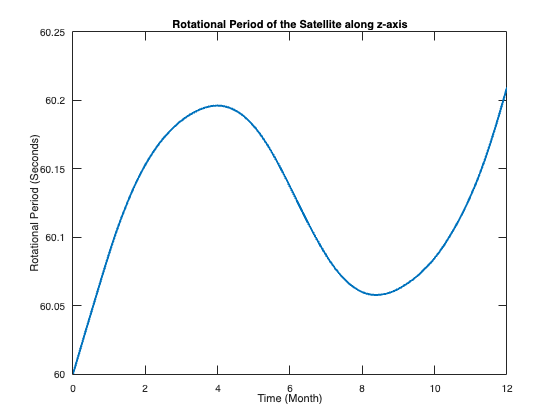

subplot(1,1,1);
plot(tt, period, 'LineWidth', 2)
title('Rotational Period of the Satellite along z-axis')
ylabel('Rotational Period (Seconds)')
xlabel('Time (Month)')
xlim([0 tt(end)])

## Angular Frequency

% AF_BF = y(:,1:3)/(2*pi)
% 
% subplot(3,1,1);
% plot(AF_BF(:,1), 'LineWidth', 2)
% title('Angular Frequency in the Satellite Body Frame')
% ylabel('Hertz in x-axis')
% xlim([0 length(t)])
% 
% subplot(3,1,2);
% plot(AF_BF(:,2), 'LineWidth', 2)
% % title('Angular Velocity in the Satellite Body Frame')
% ylabel('Hertz in y-axis')
% xlim([0 length(t)])
% 
% subplot(3,1,3);
% plot(AF_BF(:,3), 'LineWidth', 2)
% % title('Angular Velocity in the Satellite Body Frame')
% ylabel('Hertz in z-axis')
% xlabel('Time (Days)')
% xlim([0 length(t)])
% hold off

## Rotational Energy


$$E=\frac{1}{2}\left(I_1 {\omega_1 }^2 +I_2 {\omega_2 }^2 +I_3 {\omega_3 }^2 \right)$$


E_r = (1/2)*((I1*(y(:,1)).^2) + I2*(y(:,2)).^2 + I3*(y(:,3)).^2)

E_r =    31.5496
   31.5465
   31.5434
   31.5403
   31.5372
   31.5342
   31.5310
   31.5279
   31.5248
   31.5217


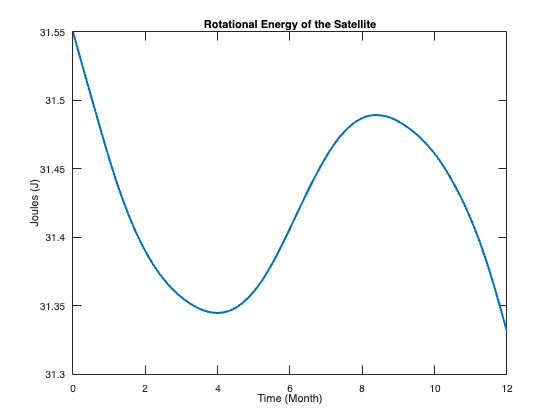

subplot(1,1,1);
plot(tt,E_r(:,1), 'LineWidth', 2)
title('Rotational Energy of the Satellite')
ylabel('Joules (J)')
xlabel('Time (Month)')
xlim([0 tt(end)])

## 3-1-3 Euler Angles

**Satellite Body Frame**

EA_313 = rad2deg(wrapTo2Pi(y(:,4:6)))

EA_313 =          0    1.0000         0
  357.2390    0.9594  345.3126
  354.4263    0.9319  305.3046
  351.3315    0.8780  239.6814
  348.0815    0.8459  148.7312
  344.5939    0.8086   32.2671
  341.2980    0.7836  250.7564
  337.3760    0.7521   83.2673
  333.5945    0.7286  250.2859
  329.6840    0.7022   31.9103


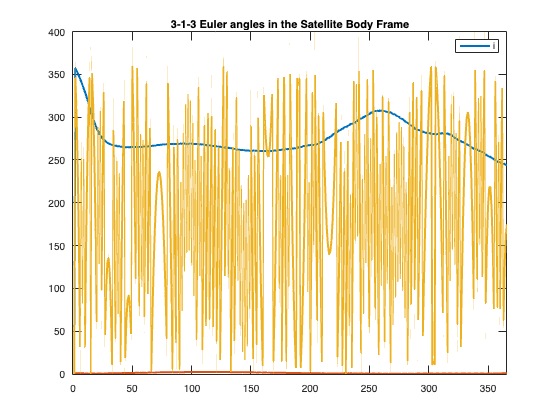

plot(EA_313(:,1:3), 'LineWidth', 2)
title('3-1-3 Euler angles in the Satellite Body Frame')
legend('i')
% xlim([0 t(end)])
xlim([0 length(t)])

**Sun "Body Frame"**

EA_S313 = rad2deg(wrapTo2Pi(y(:,13:15)))

EA_S313 =   168.7400  336.6000  114.2100
  168.7400  336.6000  115.1962
  168.7400  336.6000  116.1824
  168.7400  336.6000  117.1685
  168.7400  336.6000  118.1547
  168.7400  336.6000  119.1409
  168.7400  336.6000  120.1271
  168.7400  336.6000  121.1132
  168.7400  336.6000  122.0994
  168.7400  336.6000  123.0856


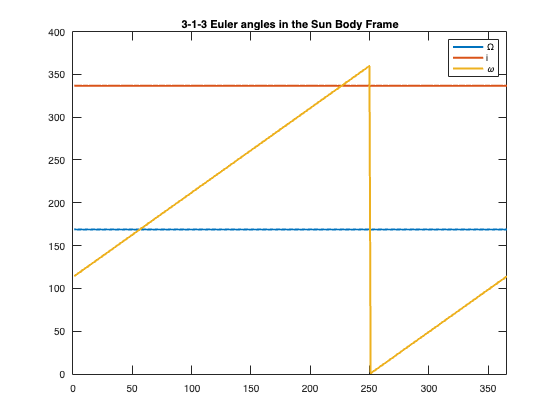

plot(EA_S313, 'LineWidth', 2)
title('3-1-3 Euler angles in the Sun Body Frame')
legend('\Omega','i','\omega')
% xlim([0 t(end)])
xlim([0 length(t)])

## Principal Axes Euler Angles

**Satellite Body Frame**

EA_BF = rad2deg(wrapToPi(y(:,7:9)))

EA_BF =          0    1.0000    1.0000
   -0.0005    1.0067  -15.0497
   -0.0017    1.0061  -56.4575
   -0.0030    1.0189 -123.6346
   -0.0046    1.0205  143.7808
   -0.0046    1.0284   25.5830
   -0.0060    1.0310 -117.6178
   -0.0057    1.0348   72.9031
   -0.0079    1.0344 -122.0602
   -0.0089    1.0371   17.4438


subplot(1,1,1);
plot(EA_BF(:,2), 'LineWidth', 2)
title('Principal axes Euler angles in the Satellite Body Frame')
legend('\phi','\theta','\psi')

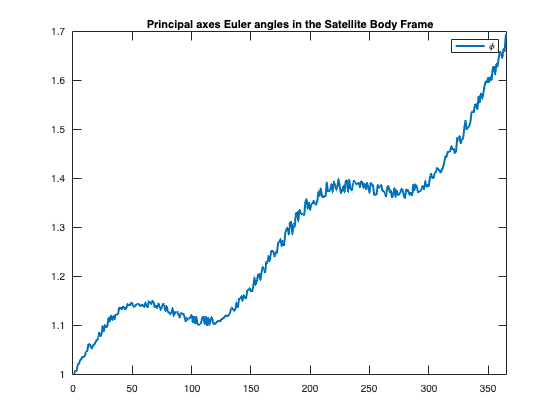

% xlim([0 t(end)])
xlim([0 length(t)])

**Sun "Body Frame"**

EA_SBF = rad2deg(wrapTo2Pi(y(:,16:18)))

EA_SBF =    76.1874   78.9875   23.4000
   76.1874   78.9875   24.3862
   76.1874   78.9875   25.3724
   76.1874   78.9875   26.3585
   76.1874   78.9875   27.3447
   76.1874   78.9875   28.3309
   76.1874   78.9875   29.3171
   76.1874   78.9875   30.3032
   76.1874   78.9875   31.2894
   76.1874   78.9875   32.2756


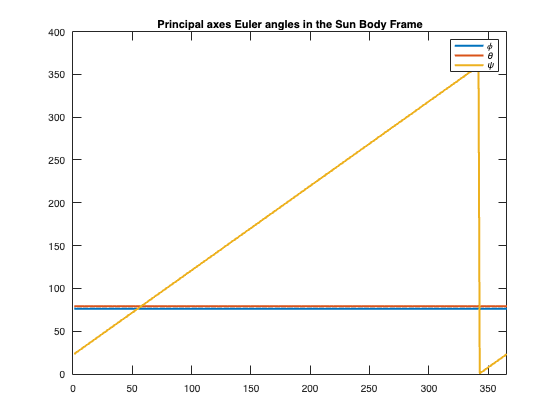

subplot(1,1,1);
plot(EA_SBF, 'LineWidth', 2)
title('Principal axes Euler angles in the Sun Body Frame')
legend('\phi','\theta','\psi')
% xlim([0 t(end)])
xlim([0 length(t)])

## Satellite Obliquity

ob = zeros(length(t), 1);
for ii = 1:length(t)
    obz = RBI123(y(ii,7),y(ii,8),y(ii,9));
    ang = subspace([obz(3,1);obz(3,2);obz(3,3)],[0;0;1]);
    ob(ii,1) = abs(rad2deg(sun_i)) + rad2deg(wrapToPi(ang)) - 1;
end
ob

ob =    23.4000
   23.4067
   23.4061
   23.4189
   23.4206
   23.4284
   23.4310
   23.4349
   23.4345
   23.4371


obz_mm = movmean(ob, (366/12))

obz_mm =    23.4338
   23.4353
   23.4367
   23.4382
   23.4397
   23.4412
   23.4432
   23.4447
   23.4462
   23.4483


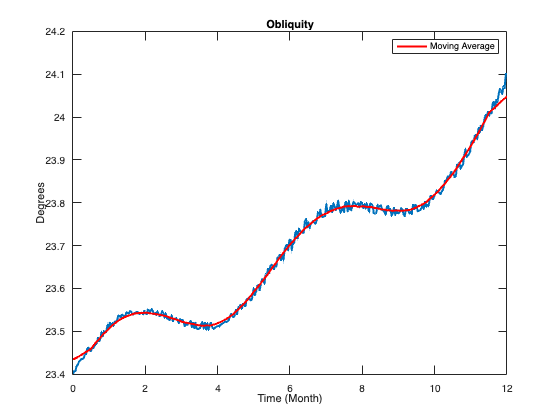

subplot(1,1,1);
plot(tt, ob, 'LineWidth', 2)
hold on
plot(tt, obz_mm, 'r', 'LineWidth', 2)
title('Obliquity')
ylabel('Degrees')
hold off
legend('','Moving Average')
xlabel('Time (Month)')
xlim([0 tt(end)])

% ob2 = zeros(length(t), 1);
% ob2313 = zeros(length(t), 1);
% for iii = 1:length(t)
%     obz2 = RBI123(y(iii,19),y(iii,20),y(iii,21));
%     obz2313 = RBI313(y(iii,16),y(iii,17),y(iii,18));
%     obz = RBI123(y(iii,10),y(iii,11),y(iii,12));
%     ang1 = subspace([obz2(3,1);obz2(3,2);obz2(3,3)],[0;0;1]);
%     ang2 = subspace([obz2313(3,1);obz2313(3,2);obz2313(3,3)],[0;0;1]);
%     % ang313 = subspace([obz2313(3,1);obz2313(3,2);obz2313(3,3)],[obz(3,1);obz(3,2);obz(3,3)]);
%     ang313 = subspace([obz2(3,1);obz2(3,2);obz2(3,3)],[obz(3,1);obz(3,2);obz(3,3)]);
%     ob2(iii,1) = abs(rad2deg(wrapToPi(ang1))-rad2deg(wrapToPi(ang2)));
%     ob2313(iii,1) = rad2deg(wrapToPi(ang313));
% end
% ob2
% ob2313
% ob_mm = movmean(ob2313, 366/12)
% subplot(1,1,1);
% plot(t, ob2313, t, ob_mm, 'LineWidth', 2)
% title('Obliquity')
% ylabel('Degrees')
% xlabel('Time (Days)')
toc

Elapsed time is 201.647585 seconds.


### Animation

% O = zeros(3);
% ijk = eye(3);
% ijk = RBI313(y(1, 4),y(1, 5),y(1, 6))*eye(3);
% lmn = RBI313(y(1, 16),y(1, 17),y(1, 18))*eye(3);
% % quiver3(O(1,1), O(1,2), O(1,3), ijk(1,1), ijk(1,2), ijk(1,3), 'r', 'LineWidth', 2)
% % hold on
% % quiver3(O(2,1), O(2,2), O(2,3), ijk(2,1), ijk(2,2), ijk(2,3), 'g', 'LineWidth', 2)
% % quiver3(O(3,1), O(3,2), O(3,3), ijk(3,1), ijk(3,2), ijk(3,3), 'b', 'LineWidth', 2)
% % plot3([-1 1], [0 0], [0 0], 'k--')
% % plot3([0 0], [-1 1], [0 0], 'k--')
% % plot3([0 0], [0 0], [-1 1], 'k--')
% % xlabel('X')
% % ylabel('Y')
% % zlabel('Z')
% % axis equal
% % axis square
% % xlim([-1 1])
% % ylim([-1 1])
% % zlim([-1 1])
% % title('Intermediate Axis Theorem 3D simulation')
% polhode = zeros(n,3);
% s_polhode = zeros(n/5,3);
% r_polhode = zeros(n,3);
% idx = 0;
% 
% nnhat = zeros(size(n_hat));
% rrhat = zeros(size(r_hat));
% for id=1:1:1000
%     hold off
%     ijk = RBI313(y(id, 4),y(id, 5),y(id, 6))*eye(3);
%     lmn = RBI313(y(id, 16),y(id, 17),y(id, 18))*eye(3);
%     % ijk = ijk';
%     % quiver3(O(1,1), O(1,2), O(1,3), ijk(1,1), ijk(1,2), ijk(1,3), 'r', 'LineWidth', 2)
%     % hold on
%     % quiver3(O(2,1), O(2,2), O(2,3), ijk(2,1), ijk(2,2), ijk(2,3), 'g', 'LineWidth', 2)
%     %polhode = plot3(ijk(2,1), ijk(2,2), ijk(2,3),'k.');
%     idx = idx + 1;
%     polhode(idx,:) = [ijk(2,1) ijk(2,2) ijk(2,3)];
% 
%     s_polhode(idx,:) = [lmn(1,1) lmn(1,2) lmn(1,3)];
%     % plot3(polhode(:,1), polhode(:,2), polhode(:,3), 'k.')
%     plot3(s_polhode(:,1), s_polhode(:,2), s_polhode(:,3), 'y*')
%     hold on
%     %hold(polhode, 'on')
%     quiver3(O(3,1), O(3,2), O(3,3), ijk(3,1), ijk(3,2), ijk(3,3), 'b', 'LineWidth', 2)
%     % polhode(idx,:) = [ijk(3,1), ijk(3,2), ijk(3,3)];
%     % plot3(polhode(:,1), polhode(:,2), polhode(:,3), 'k.')
%     %quiver3(O(3,1), O(3,2), O(3,3), 0, 1, 0, 'y', 'LineWidth', 2)
% 
%     quiver3(O(1,1), O(1,2), O(1,3), lmn(1,1), lmn(1,2), lmn(1,3), 'k', 'LineWidth', 2)      %sun vector
% 
% 
%     nnhat(1,:) = ijk'*(n_hat(1,:))';
%     nnhat(2,:) = ijk'*(n_hat(2,:))';
%     nnhat(3,:) = ijk'*(n_hat(3,:))';
%     nnhat(4,:) = ijk'*(n_hat(4,:))';
% 
% 
%     rrhat(1,:) = ijk'*(r_hat(1,:))';
%     rrhat(2,:) = ijk'*(r_hat(2,:))';
%     rrhat(3,:) = ijk'*(r_hat(3,:))';
%     rrhat(4,:) = ijk'*(r_hat(4,:))';
% 
%     r_polhode(idx,:) = [rrhat(1,1) rrhat(1,2) rrhat(1,3)];
%     plot3(r_polhode(:,1), r_polhode(:,2), r_polhode(:,3), 'k.')
% 
%     quiver3(rrhat(1,1), rrhat(1,2), rrhat(1,3), nnhat(1,1), nnhat(1,2), nnhat(1,3), 'g', 'LineWidth', 2)
%     quiver3(rrhat(2,1), rrhat(2,2), rrhat(2,3), nnhat(2,1), nnhat(2,2), nnhat(2,3), 'b', 'LineWidth', 2)
%     quiver3(rrhat(3,1), rrhat(3,2), rrhat(3,3), nnhat(3,1), nnhat(3,2), nnhat(3,3), 'g', 'LineWidth', 2)
%     quiver3(rrhat(4,1), rrhat(4,2), rrhat(4,3), nnhat(4,1), nnhat(4,2), nnhat(4,3), 'b', 'LineWidth', 2)
% 
%     quiver3(0, 0, 0, rrhat(1,1), rrhat(1,2), rrhat(1,3), 'r', 'LineWidth', 2)
%     quiver3(0, 0, 0, rrhat(2,1), rrhat(2,2), rrhat(2,3), 'r', 'LineWidth', 2)
%     quiver3(0, 0, 0, rrhat(3,1), rrhat(3,2), rrhat(3,3), 'r', 'LineWidth', 2)
%     quiver3(0, 0, 0, rrhat(4,1), rrhat(4,2), rrhat(4,3), 'r', 'LineWidth', 2)
% 
%     plot3([-1 1], [0 0], [0 0], 'k--')
%     plot3([0 0], [-1 1], [0 0], 'k--')
%     plot3([0 0], [0 0], [-1 1], 'k--')
%     xlabel('X')
%     ylabel('Y')
%     zlabel('Z')
%     axis equal
%     axis square
%     % xlim([-1 1])
%     % ylim([-1 1])
%     % zlim([-1 1])
%     xlim([-2 2])
%     ylim([-2 2])
%     zlim([-2 2])
%     title('3D simulation')
%     %legend('p','q','r')
%     drawnow
%     % disp(i)
%     % frame = getframe(gcf);
%     % img =  frame2im(frame);
%     % [img,cmap] = rgb2ind(img,256);
%     % if i == 1
%     %     imwrite(img,cmap,'animation.gif','gif','LoopCount',Inf,'DelayTime',1e-2);
%     % else
%     %     imwrite(img,cmap,'animation.gif','gif','WriteMode','append','DelayTime',1e-2);
%     % end
% end
% idx

Runge Kutta function

function dy = rot_dynamics(~,y,I)
    p = y(1);
    q = y(2);
    r = y(3);
    phi = y(4);
    theta = y(5);
    psi = y(6);
    %body_params % inertia
    w = [p; q; r]; % angular velocity
    dy(1:3) = I\(-cross(w, I*w));
    dy(4) = p+(q*sin(phi)+r*cos(phi))*tan(theta);
    dy(5) = q*cos(phi)-r*sin(phi);
    dy(6) = (q*sin(phi)+r*cos(phi))*sec(theta);
    dy = dy';
end

For ODE Solver

% function dydt = dza(t,y,I1,I2,I3, p1_nhat11, p1_nhat12, p1_nhat13, p1_nhat21, p1_nhat22, p1_nhat23, p2_nhat11, p2_nhat12, p2_nhat13, p2_nhat21, p2_nhat22, p2_nhat23, p1_rhat11, p1_rhat12, p1_rhat13, p1_rhat21, p1_rhat22, p1_rhat23, p2_rhat11, p2_rhat12, p2_rhat13, p2_rhat21, p2_rhat22, p2_rhat23, p1_rho1, p1_rho2, p2_rho1, p2_rho2, p1_s1, p1_s2, p2_s1, p2_s2, p1_e_f1, p1_e_f2, p2_e_f1, p2_e_f2, p1_e_b1, p1_e_b2, p2_e_b1, p2_e_b2, p1_A1, p1_A2, p2_A1, p2_A2)
% %     % p = y(1);
% %     % q = y(2);
% %     % r = y(3);
% %     % phi = y(4);
% %     % theta = y(5);
% %     % psi = y(6);
% %     % I1 = I(1,1);
% %     % I2 = I(2,2);
% %     % I3 = I(3,3);
% %     % dydt = zeros(6,1);
%     I0 = [I1 I2 I3];
%     I = diag(I0);
%     phi = y(4);
%     theta = y(5);
%     psi = y(6);
% 
%     omega1 = y(1)*sin(theta)*sin(psi)+y(2)*cos(psi);    %conversion of 3-1-3 angular velocity to body frame angular velocity
%     omega2 = y(1)*sin(theta)*cos(psi)-y(2)*sin(psi);    %For the Satellite
%     omega3 = y(1)*cos(theta)+y(3);
% 
%     dydt(10) = y(1)*sin(theta)*sin(psi)+y(2)*cos(psi);    %solver for body frame angles
%     dydt(11) = y(1)*sin(theta)*cos(psi)-y(2)*sin(psi);    %For the satellite
%     dydt(12) = y(1)*cos(theta)+y(3);
%     omega = [omega1; omega2; omega3];
%     % omega = [y(10); y(11); y(12)];
%     % dydt(1:3) = I\(-cross(omega, I*omega));     %omega dot in body frame
% 
%     % with torque
% 
%     s_I0 = [1 1 1];
%     s_I = diag(s_I0);
%     s_phi = y(16);
%     s_theta = y(17);
%     s_psi = y(18);
% 
%     s_omega1 = y(13)*sin(s_theta)*sin(s_psi)+y(14)*cos(s_psi);    %conversion of 3-1-3 angular velocity to body frame angular velocity
%     s_omega2 = y(13)*sin(s_theta)*cos(s_psi)-y(14)*sin(s_psi);    %For the Sun
%     s_omega3 = y(13)*cos(s_theta)+y(15);
% 
%     dydt(19) = y(13)*sin(s_theta)*sin(s_psi)+y(14)*cos(s_psi);    %solver for body frame angles
%     dydt(20) = y(13)*sin(s_theta)*cos(s_psi)-y(14)*sin(s_psi);    %For the Sun
%     dydt(21) = y(13)*cos(s_theta)+y(15);
%     s_omega = [s_omega1; s_omega2; s_omega3];
% 
%     %omega = [y(10); y(11); y(12)];
%     dydt(13:15) = s_I\(-cross(s_omega, s_I*s_omega));     %omega in body frame
% 
%     dydt(16) = ((s_omega1*sin(s_psi))/sin(s_theta)) + ((s_omega2*cos(s_psi))/sin(s_theta));      %313 Euler angles
%     dydt(17) = s_omega1*cos(s_psi) - s_omega2*sin(s_psi);
%     dydt(18) = -s_omega1*sin(s_psi)*cot(s_theta) - s_omega2*cot(s_theta) + s_omega3;
% 
%     % In = RBI123(y(10),y(11),y(12));
% 
% 
%     G = 1e+17;      %kg m/s^2, Solar radiation constant
%     R = 149.60e+9;   %m, Distance from the sun
%     P = G/(R^2);        %
%     B = 2/3;        %Lambertian
%     n_hat = [p1_nhat11 p1_nhat12 p1_nhat13; p1_nhat21 p1_nhat22 p1_nhat23; p2_nhat11 p2_nhat12 p2_nhat13; p2_nhat21 p2_nhat22 p2_nhat23];
%     r_hat = [p1_rhat11 p1_rhat12 p1_rhat13; p1_rhat21 p1_rhat22 p1_rhat23; p2_rhat11 p2_rhat12 p2_rhat13; p2_rhat21 p2_rhat22 p2_rhat23];
%     rho = [p1_rho1; p1_rho2; p2_rho1; p2_rho2];
%     s = [p1_s1; p1_s2; p2_s1; p2_s2];
%     e_f = [p1_e_f1; p1_e_f2; p2_e_f1; p2_e_f2];
%     e_b = [p1_e_b1; p1_e_b2; p2_e_b1; p2_e_b2];
%     A = [p1_A1; p1_A2; p2_A1; p2_A2];
% 
% 
%     % u = [cos(y(20))*cos(y(21)); cos(y(20))*sin(y(21)); -sin(y(20))];
%     u = [sin(y(19))*sin(y(20))*cos(y(21))-cos(y(19))*sin(y(21)); sin(y(19))*sin(y(20))*sin(y(21))+cos(y(19))*cos(y(21)); sin(y(19))*cos(y(20))];
%     % sin(d1)*sin(d2)*cos(d3)-cos(d1)*sin(d3) sin(d1)*sin(d2)*sin(d3)+cos(d1)*cos(d3) sin(d1)*cos(d2);
%     % s_u = RBI123(y(19),y(20),y(21));      %convert sun's angular position
%                                             %to a point in inertial frame
%     % u = [s_u(1,1);s_u(1,2);s_u(1,3)];     %this is the vector pointing to
%                                             %the sun
%     % nr = (RBI313(y(4),y(5),y(6)))';       %for the n-hat
%     L11 = cos(y(4))*cos(y(6)) - cos(y(5))*sin(y(4))*sin(y(6));    %this should be Omega, i, omega
%     L21 = -sin(y(6))*cos(y(4)) - cos(y(5))*sin(y(4))*cos(y(6));
%     L31 = sin(y(5))*sin(y(4));
% 
%     L12 = cos(y(6))*sin(y(4)) + cos(y(5))*cos(y(4))*sin(y(6));
%     L22 = -sin(y(6))*sin(y(4)) + cos(y(5))*cos(y(4))*cos(y(6));
%     L32 = -sin(y(5))*cos(y(4));
% 
%     L13 = sin(y(6))*sin(y(5));
%     L23 = cos(y(6))*sin(y(5));
%     L33 = cos(y(5));
% 
%     umat=[L11 L12 L13;
%         L21 L22 L23;
%         L31 L32 L33];
%     nr = umat';
% 
%     facet = length(n_hat(:,1));
%     Y = zeros(facet,length(n_hat(1,:)));
%     U = ones(3,1);
%     nh = zeros(3,1);
% 
%     for ind = 1:facet
%         % nh(:,1) = nr*(n_hat(ind,:))';
%         nh = nr*(n_hat(ind,:))';
% 
%         a_2 = B*(1-s(ind))*rho(ind) + (1-rho(ind))*B*((e_f(ind)-e_b(ind))/(e_f(ind)+e_b(ind)));
% 
%         if dot(nh, u)<=0
%             H = 0;
%         else
%             H = 1;
%         end
% 
%         Y_f = -P * (dot((rho(ind)*s(ind)*(2*(nh')*nh-U)+U), u) * dot(u, nh) + (a_2*nh*dot(nh, u))) * H*A(ind);
%         Y(ind,:) = Y_f.*-u;
%     end
%     Y = Y';
%     M = [0;0;0];
%     for i = 1:facet
%         rh = nr*(r_hat(i,:))';
%         M = M + cross(rh, Y(:,i));
%     end
%     % M = 0*M;
%     % Y_M = [0.001; 0.2; 0.0001];
%     dydt(1:3) = I\(-cross(omega, I*omega) + M);
% 
%     % dydt(4) = ((y(10)*sin(psi))/sin(theta)) + ((y(11)*cos(psi))/sin(theta));
%     % dydt(5) = y(10)*cos(psi) - y(11)*sin(psi);
%     % dydt(6) = -y(10)*sin(psi)*cot(theta) - y(11)*cot(theta) + y(12);
% 
%     % dydt(4) = ((omega1*sin(psi))/sin(theta)) + ((omega2*cos(psi))/sin(theta));
%     % dydt(5) = omega1*cos(psi) - omega2*sin(psi);
%     % dydt(6) = -omega1*sin(psi)*cot(theta) - omega2*cot(theta) + omega3;
% 
%     bmat = [sin(psi) cos(psi) 0;
%         sin(theta)*sin(psi) -sin(theta)*sin(psi) 0;
%         -cos(theta)*sin(psi) -sin(theta)*cos(psi) sin(theta)];
%     dydt(4:6) = (1/sin(theta))*(bmat*omega);
% 
% %     % dydt(4) = y(1)*sin(theta)*sin(psi)+y(2)*cos(psi);    %conversion of body frame angular velocity values to angles, for 3-1-3 matrix
% %     % dydt(5) = y(1)*sin(theta)*cos(psi)-y(2)*sin(psi);    %still to be converted
% %     % dydt(6) = y(1)*cos(theta)+y(3);
% %     % dydt(4) = (y(1)*sin(theta)*sin(psi)+y(2)*cos(psi)) * t;    %conversion of body frame angular velocity values to angles, for 3-1-3 matrix
% %     % dydt(5) = (y(1)*sin(theta)*cos(psi)-y(2)*sin(psi)) * t;
% %     % dydt(6) = (y(1)*cos(theta)+y(3)) * t;
%     % omegadot = [y(1); y(2); y(3)];
%     % dydt(7:9) = I*omegadot;
%     % dydt(7:9) = I*omega;        %angular momentum values
% %     % dydt(7:9) = [0; 1; 0]/t;
% %     %t = t + dt;
%     dydt = dydt';
% end

new

function dydt = dza(t,y,I1,I2,I3, p1_nhat11, p1_nhat12, p1_nhat13, p1_nhat21, p1_nhat22, p1_nhat23, p2_nhat11, p2_nhat12, p2_nhat13, p2_nhat21, p2_nhat22, p2_nhat23, p1_rhat11, p1_rhat12, p1_rhat13, p1_rhat21, p1_rhat22, p1_rhat23, p2_rhat11, p2_rhat12, p2_rhat13, p2_rhat21, p2_rhat22, p2_rhat23, p1_rho1, p1_rho2, p2_rho1, p2_rho2, p1_s1, p1_s2, p2_s1, p2_s2, p1_e_f1, p1_e_f2, p2_e_f1, p2_e_f2, p1_e_b1, p1_e_b2, p2_e_b1, p2_e_b2, p1_A1, p1_A2, p2_A1, p2_A2)
%     % p = y(1);
%     % q = y(2);
%     % r = y(3);
%     % phi = y(4);
%     % theta = y(5);
%     % psi = y(6);
%     % I1 = I(1,1);
%     % I2 = I(2,2);
%     % I3 = I(3,3);
%     % dydt = zeros(6,1);
    I0 = [I1 I2 I3];
    I = diag(I0);
    phi = y(4);
    theta = y(5);
    psi = y(6);

    omega1 = y(1)*sin(theta)*sin(psi)+y(2)*cos(psi);    %conversion of 3-1-3 angular velocity to body frame angular velocity
    omega2 = y(1)*sin(theta)*cos(psi)-y(2)*sin(psi);    %For the Satellite
    omega3 = y(1)*cos(theta)+y(3);

    dydt(7) = y(1)*sin(theta)*sin(psi)+y(2)*cos(psi);    %solver for body frame angles
    dydt(8) = y(1)*sin(theta)*cos(psi)-y(2)*sin(psi);    %For the satellite
    dydt(9) = y(1)*cos(theta)+y(3);
    omega = [omega1; omega2; omega3];
    % omega = [y(10); y(11); y(12)];
    % dydt(1:3) = I\(-cross(omega, I*omega));     %omega dot in body frame
    
    % with torque

    s_I0 = [1 1 1];
    s_I = diag(s_I0);
    s_phi = y(13);
    s_theta = y(14);
    s_psi = y(15);
    
    s_omega1 = y(10)*sin(s_theta)*sin(s_psi)+y(11)*cos(s_psi);    %conversion of 3-1-3 angular velocity to body frame angular velocity
    s_omega2 = y(10)*sin(s_theta)*cos(s_psi)-y(11)*sin(s_psi);    %For the Sun
    s_omega3 = y(10)*cos(s_theta)+y(12);

    dydt(16) = y(10)*sin(s_theta)*sin(s_psi)+y(11)*cos(s_psi);    %solver for body frame angles
    dydt(17) = y(10)*sin(s_theta)*cos(s_psi)-y(11)*sin(s_psi);    %For the Sun
    dydt(18) = y(10)*cos(s_theta)+y(12);
    s_omega = [s_omega1; s_omega2; s_omega3];
    
    %omega = [y(10); y(11); y(12)];
    dydt(10:12) = s_I\(-cross(s_omega, s_I*s_omega));     %omega in body frame
    
    dydt(13) = ((s_omega1*sin(s_psi))/sin(s_theta)) + ((s_omega2*cos(s_psi))/sin(s_theta));      %313 Euler angles
    dydt(14) = s_omega1*cos(s_psi) - s_omega2*sin(s_psi);
    dydt(15) = -s_omega1*sin(s_psi)*cot(s_theta) - s_omega2*cot(s_theta) + s_omega3;

    % In = RBI123(y(10),y(11),y(12));


    G = 1e+17;      %kg m/s^2, Solar radiation constant
    R = 149.60e+9;   %m, Distance from the sun
    P = G/(R^2);        %
    B = 2/3;        %Lambertian
    n_hat = [p1_nhat11 p1_nhat12 p1_nhat13; p1_nhat21 p1_nhat22 p1_nhat23; p2_nhat11 p2_nhat12 p2_nhat13; p2_nhat21 p2_nhat22 p2_nhat23];
    r_hat = [p1_rhat11 p1_rhat12 p1_rhat13; p1_rhat21 p1_rhat22 p1_rhat23; p2_rhat11 p2_rhat12 p2_rhat13; p2_rhat21 p2_rhat22 p2_rhat23];
    rho = [p1_rho1; p1_rho2; p2_rho1; p2_rho2];
    s = [p1_s1; p1_s2; p2_s1; p2_s2];
    e_f = [p1_e_f1; p1_e_f2; p2_e_f1; p2_e_f2];
    e_b = [p1_e_b1; p1_e_b2; p2_e_b1; p2_e_b2];
    A = [p1_A1; p1_A2; p2_A1; p2_A2];


    % u = [cos(y(20))*cos(y(21)); cos(y(20))*sin(y(21)); -sin(y(20))];
    u = [sin(y(16))*sin(y(17))*cos(y(18))-cos(y(16))*sin(y(18)); sin(y(16))*sin(y(17))*sin(y(18))+cos(y(16))*cos(y(18)); sin(y(16))*cos(y(17))];
    % sin(d1)*sin(d2)*cos(d3)-cos(d1)*sin(d3) sin(d1)*sin(d2)*sin(d3)+cos(d1)*cos(d3) sin(d1)*cos(d2);
    % s_u = RBI123(y(19),y(20),y(21));      %convert sun's angular position
                                            %to a point in inertial frame
    % u = [s_u(1,1);s_u(1,2);s_u(1,3)];     %this is the vector pointing to
                                            %the sun
    % nr = (RBI313(y(4),y(5),y(6)))';       %for the n-hat
    L11 = cos(y(4))*cos(y(6)) - cos(y(5))*sin(y(4))*sin(y(6));    %this should be Omega, i, omega
    L21 = -sin(y(6))*cos(y(4)) - cos(y(5))*sin(y(4))*cos(y(6));
    L31 = sin(y(5))*sin(y(4));

    L12 = cos(y(6))*sin(y(4)) + cos(y(5))*cos(y(4))*sin(y(6));
    L22 = -sin(y(6))*sin(y(4)) + cos(y(5))*cos(y(4))*cos(y(6));
    L32 = -sin(y(5))*cos(y(4));

    L13 = sin(y(6))*sin(y(5));
    L23 = cos(y(6))*sin(y(5));
    L33 = cos(y(5));

    umat=[L11 L12 L13;
        L21 L22 L23;
        L31 L32 L33];
    nr = umat';

    facet = length(n_hat(:,1));
    Y = zeros(facet,length(n_hat(1,:)));
    U = ones(3,1);
    nh = zeros(3,1);

    for ind = 1:facet
        % nh(:,1) = nr*(n_hat(ind,:))';
        nh = nr*(n_hat(ind,:))';

        a_2 = B*(1-s(ind))*rho(ind) + (1-rho(ind))*B*((e_f(ind)-e_b(ind))/(e_f(ind)+e_b(ind)));

        if dot(nh, u)<=0
            H = 0;
        else
            H = 1;
        end
        
        Y_f = -P * (dot((rho(ind)*s(ind)*(2*(nh')*nh-U)+U), u) * dot(u, nh) + (a_2*nh*dot(nh, u))) * H*A(ind);
        Y(ind,:) = Y_f.*-u;
    end
    Y = Y';
    M = [0;0;0];
    for i = 1:facet
        rh = nr*(r_hat(i,:))';
        M = M + cross(rh, Y(:,i));
    end
    % M = 0*M;
    % Y_M = [0.001; 0.2; 0.0001];
    dydt(1:3) = I\(-cross(omega, I*omega) + M);

    % dydt(4) = ((y(10)*sin(psi))/sin(theta)) + ((y(11)*cos(psi))/sin(theta));
    % dydt(5) = y(10)*cos(psi) - y(11)*sin(psi);
    % dydt(6) = -y(10)*sin(psi)*cot(theta) - y(11)*cot(theta) + y(12);

    % dydt(4) = ((omega1*sin(psi))/sin(theta)) + ((omega2*cos(psi))/sin(theta));
    % dydt(5) = omega1*cos(psi) - omega2*sin(psi);
    % dydt(6) = -omega1*sin(psi)*cot(theta) - omega2*cot(theta) + omega3;

    bmat = [sin(psi) cos(psi) 0;
        sin(theta)*sin(psi) -sin(theta)*sin(psi) 0;
        -cos(theta)*sin(psi) -sin(theta)*cos(psi) sin(theta)];
    dydt(4:6) = (1/sin(theta))*(bmat*omega);

%     % dydt(4) = y(1)*sin(theta)*sin(psi)+y(2)*cos(psi);    %conversion of body frame angular velocity values to angles, for 3-1-3 matrix
%     % dydt(5) = y(1)*sin(theta)*cos(psi)-y(2)*sin(psi);    %still to be converted
%     % dydt(6) = y(1)*cos(theta)+y(3);
%     % dydt(4) = (y(1)*sin(theta)*sin(psi)+y(2)*cos(psi)) * t;    %conversion of body frame angular velocity values to angles, for 3-1-3 matrix
%     % dydt(5) = (y(1)*sin(theta)*cos(psi)-y(2)*sin(psi)) * t;
%     % dydt(6) = (y(1)*cos(theta)+y(3)) * t;
    % omegadot = [y(1); y(2); y(3)];
    % dydt(7:9) = I*omegadot;
    % dydt(7:9) = I*omega;        %angular momentum values
%     % dydt(7:9) = [0; 1; 0]/t;
%     %t = t + dt;
    dydt = dydt';
end

function dydt = sunyorp(t,y)
    s_I0 = [1 1 1];
    s_I = diag(I0);
    s_phi = y(16);
    s_theta = y(17);
    s_psi = y(18);
    
    s_omega1 = y(13)*sin(s_theta)*sin(s_psi)+y(14)*cos(s_psi);    %conversion of 3-1-3 angular velocity to body frame angular velocity
    s_omega2 = y(13)*sin(s_theta)*cos(s_psi)-y(14)*sin(s_psi);    %For the Sun
    s_omega3 = y(13)*cos(s_theta)+y(15);

    dydt(19) = y(13)*sin(s_theta)*sin(s_psi)+y(14)*cos(s_psi);    %solver for body frame angles
    dydt(20) = y(13)*sin(s_theta)*cos(s_psi)-y(14)*sin(s_psi);    %For the Sun
    dydt(21) = y(13)*cos(s_theta)+y(15);
    s_omega = [s_omega1; s_omega2; s_omega3];
    
    %omega = [y(10); y(11); y(12)];
    dydt(13:15) = s_I\(-cross(s_omega, s_I*s_omega));     %omega in body frame
    
    dydt(16) = ((s_omega1*sin(s_psi))/sin(s_theta)) + ((s_omega2*cos(s_psi))/sin(s_theta));      %313 Euler angles
    dydt(17) = s_omega1*cos(s_psi) - s_omega2*sin(s_psi);
    dydt(18) = -s_omega1*sin(s_psi)*cot(s_theta) - s_omega2*cot(s_theta) + omega3;

    % dydt(7:9) = I*omega;        %angular momentum values
%     % dydt(7:9) = [0; 1; 0]/t;
%     %t = t + dt;
    dydt = dydt';
end


% function dydt = dza(t,y,I1,I2,I3)
%     % p = y(1);
%     % q = y(2);
%     % r = y(3);
%     % phi = y(4);
%     % theta = y(5);
%     % psi = y(6);
%     % I1 = I(1,1);
%     % I2 = I(2,2);
%     % I3 = I(3,3);
%     % dydt = zeros(6,1);
%     I0 = [I1 I2 I3];
%     I = diag(I0);
%     phi = y(4);
%     theta = y(5);
%     psi = y(6);
%     % omega1 = y(1)*sin(theta)*sin(psi)+y(2)*cos(psi);    %conversion of 3-1-3 angular velocity to body frame angular velocity
%     % omega2 = y(1)*sin(theta)*cos(psi)-y(2)*sin(psi);
%     % omega3 = y(1)*cos(theta)+y(3);
%     % omega = [omega1; omega2; omega3];
%     omega = [y(1); y(2); y(3)];
%     dydt(1:3) = I\(-cross(omega, I*omega));     %omega dot in body frame
%     %convert 3-1-3 angles to 3-2-1
%     %3-1-3 to inertial
%     % iner = RBI313(phi, theta, psi);
%     %inertial to 1-2-3
%     % pphi = atan(iner(1,2)/iner(1,1));
%     % ttheta = -asin(iner(1,3));
%     % ppsi = atan(iner(2,3)/iner(3,3));
%     % d1 = y(4);
%     % d2 = y(5);
%     % d3 = y(6);
%     % C11 = -sin(d3)*cos(d1) - cos(d2)*sin(d1)*cos(d3);
%     % C12 = cos(d3)*sin(d1) + cos(d2)*cos(d1)*sin(d3);
%     % C13 = sin(d3)*sin(d2);
%     % C23 = cos(d3)*sin(d2);
%     % C33 = cos(d2);
%     % pphi = atan(C12/C11);
%     % 
%     % ttheta = -asin(C13);
%     % ppsi = atan(C23/C33);
%     % %conversion of body frame values to inertial frame, 3-2-1 matrix,
%     % angular momentum
%     % dydt(4) = omega1+(omega2*sin(pphi)+omega3*cos(pphi))*tan(ttheta);
%     % dydt(5) = omega2*cos(pphi)-omega3*sin(pphi);
%     % dydt(6) = (omega2*sin(pphi)+omega3*cos(pphi))*sec(ttheta);
% 
%     dydt(4) = y(1)+(y(2)*sin(phi)+y(3)*cos(phi))*tan(theta);
%     dydt(5) = y(2)*cos(phi)-y(3)*sin(phi);
%     dydt(6) = (y(2)*sin(phi)+y(3)*cos(phi))*sec(theta);
% 
%     % dydt(4) = y(1)*sin(theta)*sin(psi)+y(2)*cos(psi);    %conversion of body frame angular velocity values to angles, for 3-1-3 matrix
%     % dydt(5) = y(1)*sin(theta)*cos(psi)-y(2)*sin(psi);    %still to be converted
%     % dydt(6) = y(1)*cos(theta)+y(3);
%     % dydt(4) = (y(1)*sin(theta)*sin(psi)+y(2)*cos(psi)) * t;    %conversion of body frame angular velocity values to angles, for 3-1-3 matrix
%     % dydt(5) = (y(1)*sin(theta)*cos(psi)-y(2)*sin(psi)) * t;
%     % dydt(6) = (y(1)*cos(theta)+y(3)) * t;
%     dydt(7:9) = I*omega;        %angular momentum values
%     % dydt(7:9) = [0; 1; 0]/t;
%     %t = t + dt;
%     dydt = dydt';
% end

Rotation Matrix for 1-2-3 angles

function mat=RBI123(pphi,ttheta,ppsi) 
    d1 = pphi;
    d2 = ttheta;
    d3 = ppsi;
    
    mat=[cos(d2)*cos(d3) cos(d2)*sin(d3) -sin(d2);                        %1-2-3 rotation matrix
        sin(d1)*sin(d2)*cos(d3)-cos(d1)*sin(d3) sin(d1)*sin(d2)*sin(d3)+cos(d1)*cos(d3) sin(d1)*cos(d2);
        cos(d1)*sin(d2)*cos(d3)+sin(d1)*sin(d3) cos(d1)*sin(d2)*sin(d3)-sin(d1)*cos(d3) cos(d1)*cos(d2)];

end

Rotation Matrix for 3-1-3 angles

function mat=RBI313(pphi,ttheta,ppsi) 
    d1 = pphi;
    d2 = ttheta;
    d3 = ppsi;
    

    L11 = cos(d1)*cos(d3) - cos(d2)*sin(d1)*sin(d3);    %this should be Omega, i, omega
    L21 = -sin(d3)*cos(d1) - cos(d2)*sin(d1)*cos(d3);
    L31 = sin(d2)*sin(d1);

    L12 = cos(d3)*sin(d1) + cos(d2)*cos(d1)*sin(d3);
    L22 = -sin(d3)*sin(d1) + cos(d2)*cos(d1)*cos(d3);
    L32 = -sin(d2)*cos(d1);

    L13 = sin(d3)*sin(d2);
    L23 = cos(d3)*sin(d2);
    L33 = cos(d2);

    mat=[L11 L12 L13;
        L21 L22 L23;
        L31 L32 L33];

end